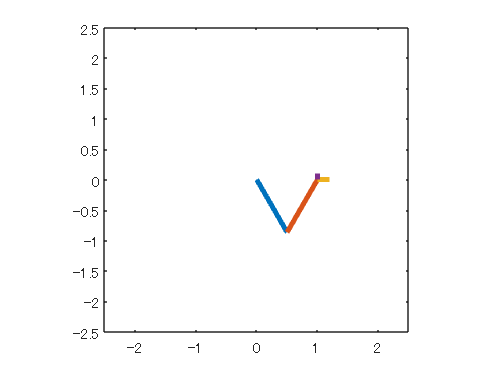

%初期化
dt = 0.05;
robot = Manipulator_3DOF_2D([-pi/3; 2*pi/3; 0], [1; 1], dt);

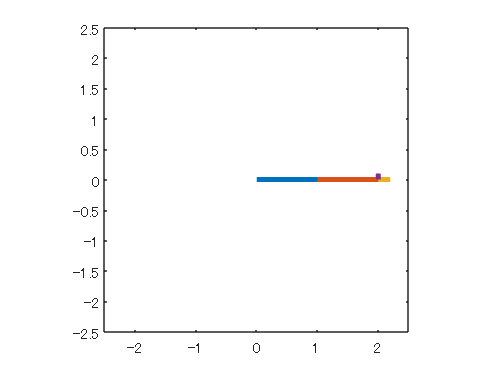


%順運動学
for angle = 0 : pi/10 : 2*pi
    robot = robot.setJointThetas([angle; angle; 0]);
    robot = robot.updateRobotState;
    robot.plotRobot;

    drawnow; 
end

%初期化
dt = 0.05;
robot = Manipulator_3DOF_2D([-pi/3; 2*pi/3; 0], [1; 1], dt);

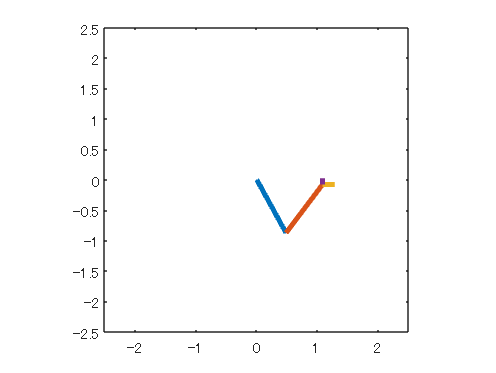


%逆運動学
theta = 0;
x = 2;
for t = 0 : dt : 3
    theta = theta + pi * dt;
    x = x - 0.3 * dt;
    robot = robot.setPosition([x; 0.5*sin(theta); 0]);
    robot = robot.setOrientation(0);
    robot = robot.calcInverseKinematics;
    robot = robot.updateRobotState;
    
    robot.plotRobot;

    drawnow; 
end

%初期化
dt = 0.05;
robot = Manipulator_3DOF_2D([-pi/3; 2*pi/3; 0], [1; 1], dt);

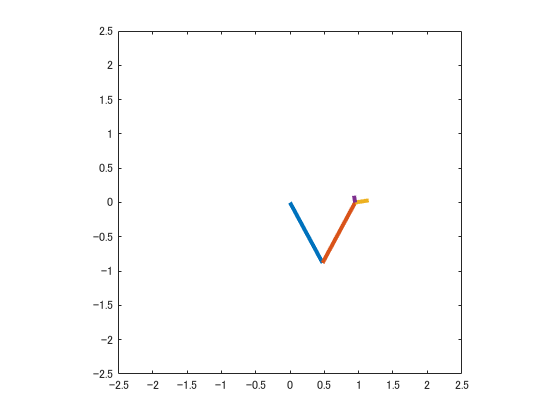


%ヤコビアン
for t = 0 : dt : 1
    robot = robot.calcInverseKinematicsUsingJacobian([-1; 0], pi); %単位：[m/s, m/s], rad/s
    robot = robot.updateRobotState;
    
    robot.plotRobot;

    drawnow; 
end

%初期化
dt = 0.05;
robot = Manipulator_3DOF_2D([-pi/3; 2*pi/3; 0], [1; 1], dt);


%軌道追従（逆行列）

